**주요 내용**

- **운동 방정식**:


$$\sum F = ma$$


- 질점에 작용하는 전체 힘은 질점의 질량과 가속도의 곱과 같음을 나타냅니다.

- **접선과 법선 성분**:

- 원운동에서는 힘이 두 가지 성분으로 나뉩니다:

- **법선 방향 힘** ($\sum F_n$):


$$ \sum F_n = ma_n = \frac{mv^2}{\rho}$$


- 여기서 $v$는 속도, $\rho$는 곡률 반경입니다.

- 법선방향 힘의 의미: 속도의 변화 중 방향변화의 힘을 의미

- **접선 방향 힘** ($\sum F_t$): 


$$\sum F_t = ma_t = m\frac{dv}{dt}$$


- 여기서 $a_t$는 접선 방향 가속도를 나타냅니다.

- 접선방향 가속도의 의미 : 전체 물체의 가속도(속도의 시간변화율)를 결정

- **힘 성분**:

- 힘은 두 가지 성분으로 나뉩니다:

- **반경 방향 힘(법선방향 = 방향변화 힘)** ($\sum F_r$):


$$ \sum F_r = ma_r = m(\ddot{r} - r\dot{\theta}^2)$$


- 여기서 $\dot{r}$은 반경의 시간 변화율,$\dot{\theta}$는 각도의 시간 변화율입니다.

- **각 방향 힘(접선방향 = 전체 가속도 결정)** ($\sum F_\theta$): 


$$\sum F_\theta = ma_\theta = m(r\ddot{\theta} + 2\dot{r}\dot{\theta})$$


**문제 설정**

- **주어진 식**:

- 각도 $\theta = 0.12t^2 \, rad$

- 반경 $r = 1.0 - 0.1t^2 \, m$

- 질량 $m = 0.3 \, kg$

$t = 0$**일 때 계산**

- **반경 **$r:$


$$r(0) = 1.0 - 0.1(0)^2 = 1.0 \, m$$


- **속도 **$˙\dot{r}: $


$$\dot{r} = -0.2(0) = 0 \, m/s$$


- **가속도 **$\ddot{r}$:


$$\ddot{r} = -0.2 \, m/s^2$$


- **각도 **$\theta$:


$$\theta(0) = 0.12(0)^2 = 0 \, rad$$


- **각속도 **$\dot{\theta}$:


$$\dot{\theta} = 0.24(0) = 0 \, rad/s$$


- **각가속도 **$\ddot{\theta}$:


$$\ddot{\theta} = 0.24 \, rad/s^2$$


**힘 성분 계산**

- **반경 방향 가속도 **$a_r$:


$$a_r = \ddot{r} - r\dot{\theta}^2 = -0.2 - 1 \cdot 0^2 = -0.2 m/s$$


- **각 방향 가속도 **$a_\theta$:


$$a_\theta = r\ddot{\theta} + 2\dot{r}\dot{\theta} = 1 \cdot 0.24 + 2 \cdot 0 \cdot 0 = 0.24 \, m/s^2$$


- **반경 방향 힘 **$F_r$:


$$F_r = ma_r = 0.3 \cdot -0.2 = -0.06 \, N$$


- **각 방향 힘 **$F_\theta$:


$$F_\theta = ma_\theta = 0.3 \cdot 0.24 = 0.072 \, N$$


$t = 2.09$**일 때 계산**

- **반경 **$r$:


$$r(2.09) = 1.0 - 0.1(2.09)^2 \approx 0.563 \, m$$


- **속도**$\dot{r}$:


$$\dot{r} = -0.2(2.09) \approx -0.418 \, m/s
$$


- **가속도**$\ddot{r}$:


$$\ddot{r} = -0.2 \, m/s^$$


- **각도 **$\theta$:


$$\theta(2.09) = 0.12(2.09)^2 \approx 0.524 \, rad$$


- **각속도 **$\dot{\theta}$:


$$\dot{\theta} = 0.24(2.09) \approx 0.502 \, rad/s$$


- **각가속도 **$\ddot{\theta}$:


$$\ddot{\theta} = 0.24 \, rad/s^2$$


**힘 성분 계산**

- **반경 방향 가속도 **$a_r$:


$$a_r = \ddot{r} - r\dot{\theta}^2 = -0.2 - 0.563(0.502)^2 \approx -0.342 \, m/s^2$$


- **각 방향 가속도 **$a_\theta$:


$$a_\theta = r\ddot{\theta} + 2\dot{r}\dot{\theta} \approx 0.563(0.24) + 2(-0.418)(0.502) \approx -0.285 \, m/s^2$$


- **반경 방향 힘 **$F_r$:


$$F_r = ma_r = 0.3 \cdot (-0.342) \approx -0.1026 \, N$$


- **각 방향 힘 **$F_\theta$:


$$F_\theta = ma_\theta = 0.3 \cdot (-0.285) \approx -0.0855 \, N$$


**결론**

- **결과**:

- $t = 0$일 때:


$$F_r = 0 \, N$$



$$F_\theta = 0.072 \, N$$


- $t = 2.09$일 때:


$$F_r \approx -0.1026 \, N$$



$$F_\theta \approx -0.0855 \, N$$


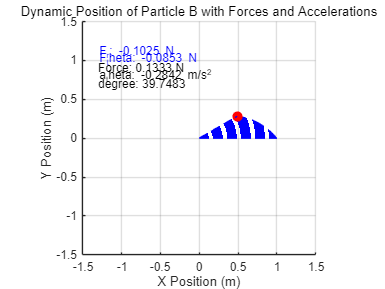

m = 0.3; % 질량 (kg)
t0 = 0; % 초기 시간
t1 = 2.09; % t = 2.09 s
num_points = 100; 

t_values = linspace(t0, t1, num_points);

F_r = zeros(1, length(t_values)); 
F_theta = zeros(1, length(t_values)); 
Force = zeros(1, length(t_values));
r_values = zeros(1, length(t_values)); 
theta_values = zeros(1, length(t_values)); 
a_r = zeros(1, length(t_values)); 
a_theta = zeros(1, length(t_values)); 

for i = 1:length(t_values)
    t = t_values(i);
    
    r_values(i) = 1 - 0.1 * t^2; 
    theta_values(i) = 0.12 * t^2; 
    
    dot_r = -0.2 * t; 
    ddot_r = -0.2; 
    dot_theta = 0.24 * t; 
    ddot_theta = 0.24; 
    
    a_r(i) = ddot_r - r_values(i) * dot_theta^2;
    
    a_theta(i) = r_values(i) * ddot_theta + 2 * dot_r * dot_theta;
    
    F_r(i) = m * a_r(i);
    
    F_theta(i) = m * a_theta(i);
    Force(i) = sqrt(F_r(i)^2 + F_theta(i)^2);
    
    tan_theta(i) = abs(F_theta(i) / F_r(i));
    theta_rad(i) = atan(tan_theta(i)); 
    theta_deg(i) = theta_rad(i) * (180 / pi);
end

figure;

hold on;
axis equal;
xlim([-1.5, 1.5]); 
ylim([-1.5, 1.5]); 
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Dynamic Position of Particle B with Forces and Accelerations');
grid on;

% 애니메이션 루프
for i = 1:num_points
    x = r_values(i) * cos(theta_values(i));
    y = r_values(i) * sin(theta_values(i));
   
    if i > 1
        delete(h); 
        delete(txt_r); 
        delete(txt_theta); 
        delete(txt_F); 
        delete(txt_a_theta); 
        delete(txt_tan); 
    end
    
    h = plot(x, y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    plot([0, x], [0, y], 'b--'); % 막대 OA 표시
    
    txt_r = text(-1.3, 1.1, sprintf('F_r: %.4f N', F_r(i)), 'FontSize', 10, 'Color', 'b');
    txt_theta = text(-1.3, 1.0, sprintf('F_theta: %.4f N', F_theta(i)), 'FontSize', 10, 'Color', 'b');
    txt_F = text(-1.3, 0.9, sprintf('Force: %.4f N', Force(i)), 'FontSize', 10, 'Color', 'k');
    txt_a_theta = text(-1.3, 0.8, sprintf('a_theta: %.4f m/s^2', a_theta(i)), 'FontSize', 10, 'Color', 'k');
    txt_tan = text(-1.3, 0.7, sprintf('degree: %.4f', theta_deg(i)), 'FontSize', 10, 'Color', 'k');
    
    pause(0.1);
end

hold off;

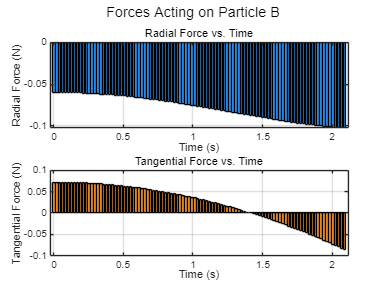

figure;

% 반경 방향 힘 시각화
subplot(2, 1, 1);
bar(t_values, F_r, 'FaceColor', [0.2 0.6 1]);
xlabel('Time (s)');
ylabel('Radial Force (N)');
title('Radial Force vs. Time');
grid on;

% 각 방향 힘 시각화
subplot(2, 1, 2);
bar(t_values, F_theta, 'FaceColor', [1 0.6 0.2]);
xlabel('Time (s)');
ylabel('Tangential Force (N)');
title('Tangential Force vs. Time');
grid on;

sgtitle('Forces Acting on Particle B');

**상단 그래프 (Radial Force)**:

- 시간에 따라 반경 방향 힘 $F_r$의 변화를 보여줍니다.

- 힘이 시간이 지남에 따라 감소하는 경향을 보입니다.

**하단 그래프 (Tangential Force)**:

- 시간에 따라 각 방향 힘$F_\theta$의 변화를 보여줍니다.

- 각 방향 힘도 감소하는 경향이 있습니다.

m = 0.3; % 질량 (kg)
t0 = 0; % 초기 시간
t1 = 2.09; % t = 2.09 s

% 시간 벡터
t_values = [t0, t1];

% 결과 저장을 위한 배열
F_r = zeros(1, length(t_values)); % 반경 방향 힘
F_theta = zeros(1, length(t_values)); % 각 방향 힘

for i = 1:length(t_values)
    t = t_values(i);
    
    % 반경 및 각도 계산
    r = 1 - 0.1 * t^2; % 반경 (m)
    dot_theta = 0.12 * t^2; % 각도 (rad)
    
    % 속도 및 가속도 계산
    dot_r = -0.2 * t; % 속도 (m/s)
    dot_theta = 0.24 * t; % 각속도 (rad/s)
    ddot_r = -0.2; % 가속도 (m/s^2)
    ddot_theta = 0.24; % 각가속도 (rad/s^2)
    
    % 반경 방향 가속도 계산
    a_r = ddot_r - r * dot_theta^2;
    
    % 각 방향 가속도 계산
    a_theta = r * ddot_theta + 2 * dot_r * dot_theta;
    
    % 반경 방향 힘 계산
    F_r(i) = m * a_r;
    
    % 각 방향 힘 계산
    F_theta(i) = m * a_theta;

    Force(i) = sqrt(F_r(i)^2 + F_theta(i)^2);
    tan_theta(i) = abs(F_theta(i) / F_r(i));
    theta_rad(i) = atan(tan_theta(i)); % theta는 라디안 단위
    theta_deg(i) = theta_rad(i) * (180 / pi);
end


fprintf('t = 0 s:\n');

t = 0 s:


fprintf('F_r = %.4f N\n', F_r(1));

F_r = -0.0600 N


fprintf('F_theta = %.4f N\n\n', F_theta(1));

F_theta = 0.0720 N



fprintf('Force = %.4f N\n\n', Force(1));

Force = 0.0937 N



fprintf('angle = %.4f degree\n\n', theta_deg(1));

angle = 50.1944 degree




fprintf('t = 2.09 s:\n');

t = 2.09 s:


fprintf('F_r = %.4f N\n', F_r(2));

F_r = -0.1025 N


fprintf('F_theta = %.4f N\n', F_theta(2));

F_theta = -0.0853 N


fprintf('Force= %.4f N\n\n', Force(2));

Force= 0.1333 N



fprintf('angle = %.4f degree\n\n', theta_deg(2));

angle = 39.7483 degree



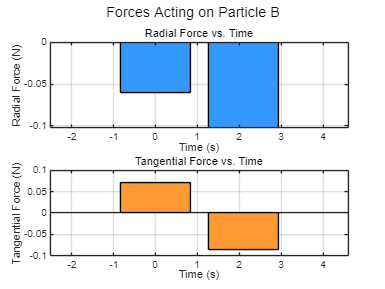


figure;

% 반경 방향 힘 시각화
subplot(2, 1, 1);
bar(t_values, F_r, 'FaceColor', [0.2 0.6 1]);
xlabel('Time (s)');
ylabel('Radial Force (N)');
title('Radial Force vs. Time');
grid on;

% 각 방향 힘 시각화
subplot(2, 1, 2);
bar(t_values, F_theta, 'FaceColor', [1 0.6 0.2]);
xlabel('Time (s)');
ylabel('Tangential Force (N)');
title('Tangential Force vs. Time');
grid on;

sgtitle('Forces Acting on Particle B');

**문제 내용**

- **물체 B**: 질량 $0.2 kg$

- **마찰계수**: $\mu_k = 0.15$

- **각속도**: $\dot{\theta} = 3 \, \text{rad/s}$

- **각가속도**: $\ddot{\theta} = 2 \, \text{rad/s}^2$

- **선속도**: $r = 0.4 \, \text{m/s}$

- **링 반지름**: $r = 0.5 \, \text{m}$

- **각도**: $\phi = 30^\circ$

**수직력 **$F_N$�

**중력의 힘 계산**:


$$W = (0.2 \, \text{kg}) \cdot (9.81 \, \text{m/s}^2) = 1.962 \, \text{N}$$


- **마찰력 계산**:

$F = \mu_k F_N = 0.15 F_N$�

**각 방향의 힘의 합**:


$$\sum F_{\theta} = m(r \ddot{\theta} + 2 \dot{r} \dot{\theta})$$


- **수직력 식**:


$$F_N - W \cos \theta = m(r \ddot{\theta} + 2 \dot{r} \dot{\theta})$$


- 이 식을 재정리하면:


$$F_N = m(r \ddot{\theta} + 2 \dot{r} \dot{\theta}) + W \cos \theta
$$


- **값 대입**:


$$F_N = (0.2 \, \text{kg}) \left[ (0.5 \, \text{m}) (2 \, \text{rad/s}^2) + (2 \cdot 0.4 \, \text{m/s})(3 \, \text{rad/s}) \right] + (1.962 \, \text{N}) \cos 30^\circ$$


- **최종 계산**:


$$F_N = (0.2)(0.5)(2) + (0.2)(2)(0.4)(3) + (1.962)(\sqrt{3}/2)$$


- 위 식을 계산하여: 


$$F_N \approx 2.38 \, \text{N}$$


- 마찰력 : $0.357 N
$ 

- 각방향의 가속도 : $3.4 m/s^2$

**물체 B의 법선방향 가속도 **$\ddot{r}$

**힘의 합 계산**:


$$\sum F_r = m (\ddot{r} - r \dot{\theta}^2)$$


**힘의 구성**:


$$-W \sin 30^\circ - 0.15 F_N = m (\ddot{r} - r \dot{\theta}^2)$$


- 여기서 $W = 1.962 \, \text{N}$이고, $F_N = 2.38 \, \text{N}$입니다.

- **값 대입**:


$$- (1.962 \, \text{N}) \sin 30^\circ - 0.15(2.38 \, \text{N}) = (0.2 \, \text{kg}) (\ddot{r} - (0.5 \, \text{m}) (3 \, \text{rad/s})^2$$


- **계산 진행**:


$$- (1.962)(0.5) - 0.357 = (0.2) (\ddot{r} - 4.5)                                         $$



$$     -0.981 - 0.357 = 0.2 \ddot{r} - 0.9$$


- **최종 정리**:


$$-1.338 = 0.2 \ddot{r} - 0.9              $$



$$                0.2 \ddot{r} = -1.338 + 0.9                  $$



$$                    0.2 \ddot{r} = -0.438               $$



$$         \ddot{r} = \frac{-0.438}{0.2} = -2.19 \, \text{m/s}^2$$


% 물리적 상수 정의
m = 0.2;                   % 질량 (kg)
g = 9.81;                  % 중력 가속도 (m/s^2)
mu_k = 0.15;               % 마찰계수
r = 0.5;                   % 반지름 (m)
dot_r = 0.4;               % 선속도 (m/s)
ddot_theta = 2;            % 각가속도 (rad/s^2)
dot_theta = 3;             % 각속도 (rad/s)
theta = 30;                % 각도

% 중력의 힘 계산
W = m * g;                 % 중력 (N)

% 중력의 수평 성분
W_cos_theta = W * cosd(theta); % cos(30도) 사용

% 수직력 계산을 위한 각 항 계산
F_N_contribution = m * (r * ddot_theta^2 + 2 * dot_r * ddot_theta);

% 수직력 F_N 계산
F_N = F_N_contribution + W_cos_theta;

% 법선 방향 가속도 계산
F_friction = mu_k * F_N;  % 마찰력
F_r = W * sind(theta) + F_friction;  % radial force

% 법선 방향 가속도 식 정리
ddot_r = -(F_r / m) + r * dot_theta^2;  % 법선 방향 가속도

% 결과 출력
fprintf('수직력 F_N: %.2f N\n', F_N);

수직력 F_N: 2.42 N


fprintf('법선 방향 가속도 ddot{r}: %.2f m/s^2\n', ddot_r);

법선 방향 가속도 ddot{r}: -2.22 m/s^2


**1. **$r(t)$** 방정식 유도**

반경 방향 가속도$\ddot{r} = -2.19 \, \text{m/s}^2$가 주어졌으므로, 이를 적분하여 시간 $t$에 따른 반지름 $r(t)$를 구할 수 있습니다.

**가정:**

- 초기 반지름 


$$r(0) = 0.5 \, \text{m}$$


- 초기 속도 


$$\dot{r}(0) = 0.4 \, \text{m/s}$$


**1차 적분 (속도):**


$$\dot{r}(t) = \dot{r}(0) + \ddot{r} \cdot t = 0.4 \, \text{m/s} - 2.19 \, \text{m/s}^2 \cdot t$$


**2차 적분 (위치):**


$$r(t) = r(0) + \dot{r}(0) \cdot t + \frac{1}{2} \ddot{r} \cdot t^2                             $$



$$                           r(t) = 0.5 \, \text{m} + 0.4 \, \text{m/s} \cdot t - \frac{1}{2} \cdot 2.19 \, \text{m/s}^2 \cdot t^2                                                    $$



$$               r(t) = 0.5 + 0.4t - 1.095t^2$$


따라서, 반지름 $r(t)$에 대한 방정식은:


$$r(t) = 0.5 + 0.4t - 1.095t^2$$


**2. **$\theta(t)$** 방정식 유도**

각속도 $\dot{\theta} = 3 \, \text{rad/s}$와 각가속도 $\ddot{\theta} = 2 \, \text{rad/s}^2$가 주어졌으므로, 이를 적분하여 시간에 따른 각도 $\theta(t)$를 구할 수 있습니다.

**가정:**

- 초기 각도 $\theta(0) = 0$

- 초기 각속도$\dot{\theta}(0) = 3 \, \text{rad/s}$

**1차 적분 (각속도):**


$$\dot{\theta}(t) = \dot{\theta}(0) + \ddot{\theta} \cdot t = 3 \, \text{rad/s} + 2 \, \text{rad/s}^2 \cdot t$$


**2차 적분 (각도):**


$$\theta(t) = \theta(0) + \dot{\theta}(0) \cdot t + \frac{1}{2} \ddot{\theta} \cdot t^2                                                      $$



$$\theta(t) = 0 + 3 \, \text{rad/s} \cdot t + \frac{1}{2} \cdot 2 \, \text{rad/s}^2 \cdot t^2  $$



$$                                                     \theta(t) = 3t + t^2$$


따라서, 각도 $\theta(t)$에 대한 방정식은:


$$\theta(t) = 3t + t^2$$


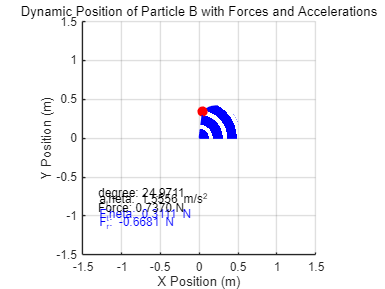

% 물리적 상수 정의
m = 0.2;                   % 질량 (kg)
g = 9.81;                  % 중력 가속도 (m/s^2)
mu_k = 0.15;               % 마찰계수
r = 0.5;                   % 반지름 (m)
dot_r = 0.4;               % 선속도 (m/s)
ddot_theta = 2;            % 각가속도 (rad/s^2)
dot_theta = 3;             % 각속도 (rad/s)
theta = 30;                % 각도

t0 = 0; % 초기 시간
t1 = 0.6; 
num_points = 100; 


t_values = linspace(t0, t1, num_points);

F_r = zeros(1, length(t_values)); 
F_theta = zeros(1, length(t_values)); 
Force = zeros(1, length(t_values));
r_values = zeros(1, length(t_values)); 
theta_values = zeros(1, length(t_values)); 
a_r = zeros(1, length(t_values)); 
a_theta = zeros(1, length(t_values)); 

for i = 1:length(t_values)
    t = t_values(i);
    
    r_values(i) = 0.5 + 0.4 * t - 1.095 * t^2; 
    theta_values(i) = 3*t - t^2; 
    
    dot_r = 0.4 * t; 
    ddot_r = -2.22; 
    dot_theta = 3 * t; 
    ddot_theta = 2; 
    
    a_r(i) = ddot_r - r_values(i) * dot_theta^2;
    
    a_theta(i) = r_values(i) * ddot_theta + 2 * dot_r * dot_theta;
    
    F_r(i) = m * a_r(i) ;
    
    F_theta(i) = m * a_theta(i);
    Force(i) = sqrt(F_r(i)^2 + F_theta(i)^2);
    
    tan_theta(i) = abs(F_theta(i) / F_r(i));
    theta_rad(i) = atan(tan_theta(i)); 
    theta_deg(i) = theta_rad(i) * (180 / pi);
end

figure;

hold on;
axis equal;
xlim([-1.5, 1.5]); 
ylim([-1.5, 1.5]); 
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Dynamic Position of Particle B with Forces and Accelerations');
grid on;

% 애니메이션 루프
for i = 1:num_points
    x = r_values(i) * cos(theta_values(i));
    y = r_values(i) * sin(theta_values(i));
   
    if i > 1
        delete(h); 
        delete(txt_r); 
        delete(txt_theta); 
        delete(txt_F); 
        delete(txt_a_theta); 
        delete(txt_tan); 
    end
    
    h = plot(x, y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    plot([0, x], [0, y], 'b--'); % 막대 OA 표시
    
    txt_r = text(-1.3, -1.1, sprintf('F_r: %.4f N', F_r(i)), 'FontSize', 10, 'Color', 'b');
    txt_theta = text(-1.3, -1.0, sprintf('F_theta: %.4f N', F_theta(i)), 'FontSize', 10, 'Color', 'b');
    txt_F = text(-1.3, -0.9, sprintf('Force: %.4f N', Force(i)), 'FontSize', 10, 'Color', 'k');
    txt_a_theta = text(-1.3, -0.8, sprintf('a_theta: %.4f m/s^2', a_theta(i)), 'FontSize', 10, 'Color', 'k');
    txt_tan = text(-1.3, -0.7, sprintf('degree: %.4f', theta_deg(i)), 'FontSize', 10, 'Color', 'k');
    
    pause(0.1);
end

hold off;

**문제 요약 및 해석**

- **각도**: $\theta = 30^\circ$

- **각속도**: $\dot{\theta} = 1 \, \text{rad/s}$

- **각가속도**: $\ddot{\theta} = 0$

- **반지름**: $r = 0.5 \, \text{m}$

- **중력**: $W = mg$

- 
$$m = 0.3 kg$$


**주어진 힘**

- **수평 성분**:$F_r = W \cos(30^\circ)$

- **수직 성분**:$F_\theta = -W \sin(30^\circ)$

**운동 방정식**

- **접선 방향 운동방정식**: $F_\theta = m a_\theta = m (r \ddot{\theta} + 2 \dot{r}\dot{\theta})$

**각가속도 **$\ddot{\theta}$** 식으로 변환**

- 주어진 $\ddot{\theta} = 0$을 대입하여 접선 방향 운동방정식을 정리하면: 


$$2r\dot{\theta} = \frac{F_\theta}{m} = -\frac{mg \sin(30^\circ)}{m} = -g \sin(30^\circ)$$


- 법선 방향 가속도 $\dot{r}$을 구하기 위해 위의 식을 정리합니다: 

$2r\dot{\theta} = -g \sin(30^\circ)$�

�

**법선 방향 속도(**$\dot{r}$**) 계산**

- **중력 가속도** $g$를 사용하여$\dot{r}$을 계산합니다:


$$g \approx 9.81 \, \text{m/s}^2$$


- $\sin(30^\circ)$ 계산: 


$$\sin(30^\circ) = 0.5$$


- $\dot{r}$** 계산**:


$$\dot{r} = -\frac{9.81 \cdot 0.5}{2} = -\frac{4.905}{2} = -2.4525 \, \text{m/s}$$


**법선 방향 가속도(**$\ddot{r}
$**) 계산**

- **법선 방향 가속도** $\ddot{r}$ 계산:

- **법선방향 운동방정식**:$F_r = m a_r = m(\ddot{r} - r \dot{\theta}^2)$

- **법선 방향 가속도 식**:

$\ddot{r} - r \dot{\theta}^2 = \frac{F_r}{m}$��

- **법선 방향 가속도**$\ddot{r}$구하기:


$$\ddot{r} = r \dot{\theta}^2 + \frac{F_r}{m} $$


$= r \dot{\theta}^2+ \frac{mg \cos(30^\circ)}{m}$�

- **구체적인 값 대입**:

- 
$$r = 0.5 \, \text{m}$$


- 
$$\dot{\theta} = 1 \, \text{rad/s}$$


- 중력 $g = 9.81 \, \text{m/s}^2$

- **최종 계산**:

$\ddot{r} = (0.5)(1)^2 + \frac{(9.81)(\cos(30^\circ))}{1}$�

**최종 가속도 계산**

- $\cos(30^\circ) \approx 0.866$를 사용하여 최종 가속도 $\ddot{r}$를 구합니다:


$$\ddot{r} = 0.5 + (9.81)(0.866) = 0.5 + 8.51 = 9.0 \, \text{m/s}^2$$


% 물리적 상수 정의
m = 0.3;                   % 질량 (kg)
g = 9.81;                  % 중력 가속도 (m/s^2)
theta = 30;                % 각도 (degrees)
r = 0.5;                   % 반지름 (m)
dot_theta = 1;             % 각속도 (rad/s)

% 중력 계산
W = m * g;                 % 중력 (N)

% 힘 계산
F_r = W * cosd(theta);     % 법선 방향 중력의 힘  
F_t = -W * sind(theta);    % 접선 방향 중력의 힘

% 법선 방향 속도 계산
dot_r = (F_t / m) /2;          % 법선 방향 속도

% 결과 출력
fprintf('접선 방향 가속도 dot(r): %.2f m/s^2\n', dot_r);

접선 방향 가속도 dot(r): -2.45 m/s^2



% 법선 방향 가속도 계산
ddot_r = r * dot_theta^2 + (F_r / m);  % 법선 방향 가속도

% 결과 출력
fprintf('법선 방향 가속도 ddot(r): %.2f m/s^2\n', ddot_r);

법선 방향 가속도 ddot(r): 9.00 m/s^2


$r(t) $**방정식 유도**

앞서 계산한 반경 방향 가속도$\ddot{r}$는 $9.0 \, \text{m/s}^2$로 주어졌습니다. 이를 이용해 시간에 따른 반경 방향 속도와 위치 방정식을 구합니다.

**1차 적분 (속도 **$\dot{r}(t)$**):**


$$\dot{r}(t) = \dot{r}(0) + \ddot{r} \cdot t$$


초기 속도가 $\dot{r}(0) = -2.4525 \, \text{m/s}$이고, $\ddot{r} = 9.0 \, \text{m/s}^2$이므로:


$$\dot{r}(t) = -2.4525 + 9.0 \cdot t$$


**2차 적분 (위치**$ r(t)$**):**


$$r(t) = r(0) + \dot{r}(0) \cdot t + \frac{1}{2} \ddot{r} \cdot t^2$$


값을 대입하여:


$$r(t) = 0.5 + (-2.4525) \cdot t + \frac{1}{2} \cdot 9.0 \cdot t^2                                                                      $$



$$r(t) = 0.5 - 2.4525 t + 4.5 t^2$$


$\theta (t)$** 방정식 유도**

각속도 $\dot{\theta} = 1 \, \text{rad/s}$가 일정하므로, 각도 $\theta(t)$는 각속도를 시간에 대해 적분하여 구할 수 있습니다.

**1차 적분 (각도 **$\theta(t)$**):**


$$\theta(t) = \theta(0) + \dot{\theta}(0) \cdot t$$


초기 각도 $\theta(0) = 30^\circ = \frac{\pi}{6} \, \text{rad}$이므로:


$$\theta(t) = \frac{\pi}{6} + 1 \cdot t                                         
       $$



$$       \theta(t) = \frac{\pi}{6} + t$$


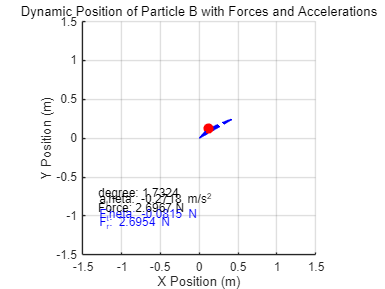

m = 0.3; % 질량 (kg)
t0 = 0; % 초기 시간
t1 = 0.3; 
num_points = 100; 

t_values = linspace(t0, t1, num_points);

F_r = zeros(1, length(t_values)); 
F_theta = zeros(1, length(t_values)); 
Force = zeros(1, length(t_values));
r_values = zeros(1, length(t_values)); 
theta_values = zeros(1, length(t_values)); 
a_r = zeros(1, length(t_values)); 
a_theta = zeros(1, length(t_values)); 

for i = 1:length(t_values)
    t = t_values(i);
    
    r_values(i) = 0.5 - 2.4525*t + 4.5 * t^2; 
    theta_values(i) = pi/6 + t; 
    
    dot_r = -2.45 * t; 
    ddot_r = 9; 
    dot_theta = 1 * t; 
    ddot_theta = 1; 
    
    a_r(i) = ddot_r - r_values(i) * dot_theta^2;
    
    a_theta(i) = r_values(i) * ddot_theta + 2 * dot_r * dot_theta;
    
    F_r(i) = m * a_r(i);
    
    F_theta(i) = m * a_theta(i);
    Force(i) = sqrt(F_r(i)^2 + F_theta(i)^2);
    
    tan_theta(i) = abs(F_theta(i) / F_r(i));
    theta_rad(i) = atan(tan_theta(i)); 
    theta_deg(i) = theta_rad(i) * (180 / pi);
end

figure;

hold on;
axis equal;
xlim([-1.5, 1.5]); 
ylim([-1.5, 1.5]); 
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Dynamic Position of Particle B with Forces and Accelerations');
grid on;

% 애니메이션 루프
for i = 1:num_points
    x = r_values(i) * cos(theta_values(i));
    y = r_values(i) * sin(theta_values(i));
   
    if i > 1
        delete(h); 
        delete(txt_r); 
        delete(txt_theta); 
        delete(txt_F); 
        delete(txt_a_theta); 
        delete(txt_tan); 
    end
    
    h = plot(x, y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    plot([0, x], [0, y], 'b--'); % 막대 OA 표시
    
    txt_r = text(-1.3, -1.1, sprintf('F_r: %.4f N', F_r(i)), 'FontSize', 10, 'Color', 'b');
    txt_theta = text(-1.3, -1.0, sprintf('F_theta: %.4f N', F_theta(i)), 'FontSize', 10, 'Color', 'b');
    txt_F = text(-1.3, -0.9, sprintf('Force: %.4f N', Force(i)), 'FontSize', 10, 'Color', 'k');
    txt_a_theta = text(-1.3, -0.8, sprintf('a_theta: %.4f m/s^2', a_theta(i)), 'FontSize', 10, 'Color', 'k');
    txt_tan = text(-1.3, -0.7, sprintf('degree: %.4f', theta_deg(i)), 'FontSize', 10, 'Color', 'k');
    
    pause(0.1);
end

hold off;

**주어진 조건:**

- 블록 B의 질량 $m = 0.2 \, kg$

- 각속도 $\dot{\theta} = 3 \, rad/s$

- 주어진 위치에서의 $r = 0.5 \, m$및 $ \dot{r} = 0.4 \, m/s$

접선방향 방정식:


$$F_N = m(r\ddot{\theta} + 2\dot{r}\dot{\theta})$$


이 식에서:

- 
$$\dot{\theta} = 3 \, rad/s$$


- $\ddot{\theta} = 0$ (각가속도가 없다는 의미)

- 
$$\dot{r} = 0.4 \, m/s$$


이를 적용하여 계산하면:


$$F_N = (0.2 \, kg)[0 + 2(0.4 \, m/s)(3 \, rad/s)]                                    $$



$$                F_N = 0.48 \, N$$


법선 운동 방정식에서 외력이 없으므로  


$$∑Fr=mar$$


$0=m(r¨-r\theta ˙2)$�


$$\ddot{r} = r\dot{\theta}^2$$


값을 대입하면:


$$\ddot{r} = (0.5 \, m)(3 \, rad/s)^2 = 4.5 \, m/s^2$$


% 초기 값 설정
m = 0.2; % 질량 (kg)
r = 0.5; % 거리 (m)
theta_dot = 3; % 각속도 (rad/s)
r_dot = 0.4; % r의 변화율 (m/s)

% 방사 가속도 계산 (a_r)
a_r = r * theta_dot^2;

% 수직력 계산 (F_N)
F_N = m * (r * 0 + 2 * r_dot * theta_dot); % theta 이중미분이 0이므로 생략

% 결과 출력
fprintf('방사 가속도 (a_r): %.2f m/s^2\n', a_r);

방사 가속도 (a_r): 4.50 m/s^2


fprintf('수직력 (F_N): %.2f N\n', F_N);

수직력 (F_N): 0.48 N


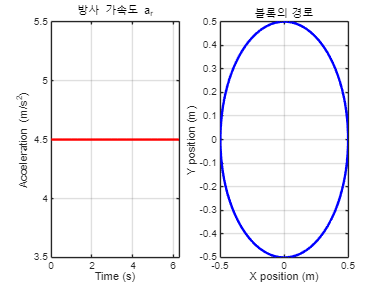


% 시각화를 위한 시간 변수 생성
t = linspace(0, 2*pi, 100); % 시간 축 (0 ~ 2*pi)

% 블록의 극좌표 경로 (r, theta) 시각화
x = r * cos(t); % x 좌표
y = r * sin(t); % y 좌표

% 그래프 그리기
figure;
subplot(1,2,1);
plot(t, a_r * ones(size(t)), 'r', 'LineWidth', 2);
title('방사 가속도 a_r');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
grid on;

subplot(1,2,2);
plot(x, y, 'b', 'LineWidth', 2);
title('블록의 경로');
xlabel('X position (m)');
ylabel('Y position (m)');
grid on;

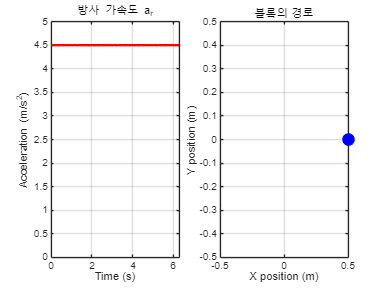

% 초기 값 설정
m = 0.2; % 질량 (kg)
r = 0.5; % 거리 (m)
theta_dot = 3; % 각속도 (rad/s)
r_dot = 0.4; % r의 변화율 (m/s)

% 방사 가속도 계산 (a_r)
a_r = r * theta_dot^2;

% 수직력 계산 (F_N)
F_N = m * (r * 0 + 2 * r_dot * theta_dot); % theta 이중미분이 0이므로 생략

% 애니메이션을 위한 시간 설정
t = linspace(0, 2*pi, 100); % 시간 축 (0 ~ 2*pi)
x = r * cos(theta_dot * t); % x 좌표
y = r * sin(theta_dot * t); % y 좌표

% 동적 그래프 생성
figure;
subplot(1, 2, 1);
h1 = plot(0, a_r, 'r', 'LineWidth', 2);
title('방사 가속도 a_r');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
axis([0 2*pi 0 5]); % 축 범위 설정
grid on;
hold on;

subplot(1, 2, 2);
h2 = plot(0, 0, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
title('블록의 경로');
xlabel('X position (m)');
ylabel('Y position (m)');
axis([-r r -r r]); % 축 범위 설정
grid on;
hold on;

% 애니메이션 실행
for i = 1:length(t)
    % 첫 번째 그래프: 방사 가속도
    subplot(1, 2, 1);
    set(h1, 'XData', t(1:i), 'YData', a_r * ones(1, i)); % 방사 가속도는 일정

    % 두 번째 그래프: 블록 경로
    subplot(1, 2, 2);
    set(h2, 'XData', x(i), 'YData', y(i)); % x, y 좌표 업데이트
    
    % 그래프 업데이트
    drawnow;
    
    % 잠시 멈춤으로 동적 효과 생성
    pause(0.05);
end

**1. 시간에 따른 **$\theta(t)$** 방정식**

주어진 각속도 $\dot{\theta} = 3 \, rad/s$는 일정한 상수입니다. 각속도는 각도 변화율이므로, 이를 적분하면 시간에 따른 각도$\theta(t)$를 구할 수 있습니다.


$$\dot{\theta} = \frac{d\theta}{dt} = 3 \, rad/s$$


적분하면:


$$\theta(t) = \theta_0 + \dot{\theta} t = \theta_0 + 3t$$


따라서 시간에 따른 각도는:


$$\theta(t) = \theta_0 + 3t$$


여기서 $\theta_0$�는 초기 각도입니다. 만약 초기 각도가 0이라면$\theta_0 = 0$이므로:


$$\theta(t) = 3t$$


**2. 시간에 따른 **$r(t)$**방정식**

$\dot{r} = 0.4 \, m/s$가 상수로 주어졌습니다. 이 역시 반지름의 변화율이므로, 이를 적분하여 시간에 따른 $ r(t)$를 구할 수 있습니다.


$$\dot{r} = \frac{dr}{dt} = 0.4 \, m/s$$


적분하면:


$$r(t) = r_0 + \dot{r} t = 0.5 + 0.4t$$


따라서 시간에 따른 반지름은:


$$r(t) = 0.5 + 0.4t$$


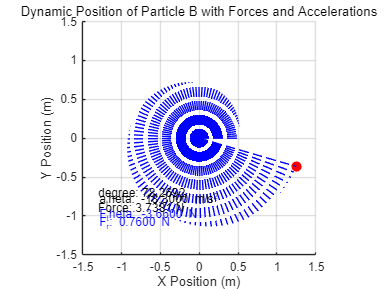

m = 0.2; % 질량 (kg)
t0 = 0; % 초기 시간
t1 = 2; 
num_points = 100; 

t_values = linspace(t0, t1, num_points);

F_r = zeros(1, length(t_values)); 
F_theta = zeros(1, length(t_values)); 
Force = zeros(1, length(t_values));
r_values = zeros(1, length(t_values)); 
theta_values = zeros(1, length(t_values)); 
a_r = zeros(1, length(t_values)); 
a_theta = zeros(1, length(t_values)); 

for i = 1:length(t_values)
    t = t_values(i);
    
    r_values(i) = 0.5 + 0.4*t; 
    theta_values(i) = 3 * t; 
    
    dot_r = -2.45 * t; 
    ddot_r = 9; 
    dot_theta = 1 * t; 
    ddot_theta = 1; 
    
    a_r(i) = ddot_r - r_values(i) * dot_theta^2;
    
    a_theta(i) = r_values(i) * ddot_theta + 2 * dot_r * dot_theta;
    
    F_r(i) = m * a_r(i);
    
    F_theta(i) = m * a_theta(i);
    Force(i) = sqrt(F_r(i)^2 + F_theta(i)^2);
    
    tan_theta(i) = abs(F_theta(i) / F_r(i));
    theta_rad(i) = atan(tan_theta(i)); 
    theta_deg(i) = theta_rad(i) * (180 / pi);
end

figure;

hold on;
axis equal;
xlim([-1.5, 1.5]); 
ylim([-1.5, 1.5]); 
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Dynamic Position of Particle B with Forces and Accelerations');
grid on;

% 애니메이션 루프
for i = 1:num_points
    x = r_values(i) * cos(theta_values(i));
    y = r_values(i) * sin(theta_values(i));
   
    if i > 1
        delete(h); 
        delete(txt_r); 
        delete(txt_theta); 
        delete(txt_F); 
        delete(txt_a_theta); 
        delete(txt_tan); 
    end
    
    h = plot(x, y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    plot([0, x], [0, y], 'b--'); % 막대 OA 표시
    
    txt_r = text(-1.3, -1.1, sprintf('F_r: %.4f N', F_r(i)), 'FontSize', 10, 'Color', 'b');
    txt_theta = text(-1.3, -1.0, sprintf('F_theta: %.4f N', F_theta(i)), 'FontSize', 10, 'Color', 'b');
    txt_F = text(-1.3, -0.9, sprintf('Force: %.4f N', Force(i)), 'FontSize', 10, 'Color', 'k');
    txt_a_theta = text(-1.3, -0.8, sprintf('a_theta: %.4f m/s^2', a_theta(i)), 'FontSize', 10, 'Color', 'k');
    txt_tan = text(-1.3, -0.7, sprintf('degree: %.4f', theta_deg(i)), 'FontSize', 10, 'Color', 'k');
    
    pause(0.1);
end

hold off;

**문제 요약:**

- 질량 $m = 0.2 \, kg$인 블록 B가 수평면 내에서 일정한 속도 $\dot{\theta} = 3 \, rad/s$로 회전하는 막대 OA를 따라 자유롭게 미끄러집니다.

- 블록과 막대 사이의 운동 마찰 계수 $\mu_k = 0.15$입니다.

- 주어진 위치에서$r = 0.5 \, m, \dot{r} = 0.4 \, m/s, \theta = 30^\circ$입니다.

**주어진 조건:**

- 
$$\dot{\theta} = 3 \, rad/s, \ddot{\theta} = 0$$


- 
$$r = 0.5 \, m$$


- 
$$\mu_k = 0.15$$


- 마찰 없는 경우 $\mu_k = 0$도 고려해야 함

**수직력구하기**

- 접선 방향 힘의 합 $\sum F_\theta:                  \sum F_\theta = m(r\ddot{\theta} + 2\dot{r}\dot{\theta})$

- 수직력 $F_N$과 중력 성분의 관계:


$$F_N - W \cos\theta = m(r\ddot{\theta} + 2\dot{r}\dot{\theta})$$


- 여기서 $W = mg, g = 9.81 \, m/s^2, \theta = 30^\circ$입니다.

- 수직력 $F_N$을 구하기 위한 계산 과정: 중력의 수직 성분은 $W \cos\theta = (1.962 \, N) \cos 30^\circ$로 계산됩니다.


$$F_N - (1.962 \, N) \cos 30^\circ = (0.2 \, kg) \left[ 0 + 2(0.4 \, m/s)(3 \, rad/s) \right]     
   $$



$$                                                                                                                        
             F_N - (1.962 \, N)(0.866) = 0.2 \, kg \times 2.4 \, m/s^2                                                                     
$$



$$                                                                F_N - 1.699 \, N = 0.48 \, N          $$



$$                                                                    F_N = 0.48 \, N + 1.699 \, N = 2.18 \, N$$


- 따라서, 마찰 계수가 $\mu_k = 0.15$일 때 수직력$F_N = 2.18 \, N$로 계산됩니다

**법선방향의 힘을 이용해 법선 가속도 구하기**

**1. 방사 방향 힘의 합 **$\sum F_r$**:**

방사 방향에서의 가속도를 계산하기 위해 다음과 같은 방정식이 사용됩니다:


$$\sum F_r = m (\ddot{r} - r \dot{\theta}^2)$$


이때 방사 방향으로 작용하는 힘은 다음과 같이 주어집니다:


$$-W \sin 30^\circ - 0.15 F_N = m (\ddot{r} - r \dot{\theta}^2)$$


여기서:

- 
$$W = mg = 0.2 \times 9.81 = 1.962 \, N$$


- $F_N = 2.18 \, N$ (이전 단계에서 계산된 수직력)

- 
$$r = 0.5 \, m, \dot{\theta} = 3 \, rad/s$$


**2. 방사 가속도**$\ddot{r}$** 계산 과정:**

방사 가속도를 구하기 위해 위 식을 $\ddot{r}$에 대해 정리합니다.

**힘의 방정식:**


$$-(1.962 \, N) \sin 30^\circ - 0.15 \times 2.18 \, N = 0.2 \, kg \left( \ddot{r} - (0.5 \, m)(3 \, rad/s)^2 \right)$$


여기서 중력의 수평 성분을 계산하면:


$$(1.962 \, N) \sin 30^\circ = 0.981 \, N$$


따라서 방정식은:


$$-0.981 \, N - 0.327 \, N = 0.2 \, kg \left( \ddot{r} - (0.5 \times 9) \right)                                                      
                  $$



$$           -1.308 \, N = 0.2 \, kg \left( \ddot{r} - 4.5 \right)$$


$\ddot{r}$** 정리:**


$$-1.308 = 0.2 (\ddot{r} - 4.5)$$


양변을 0.2로 나누면:


$$-6.54 = \ddot{r} - 4.5$$


따라서:


$$\ddot{r} = -6.54 + 4.5 = -2.04 \, m/s^2$$


**접선 방향 힘의 합 **$\sum F_\theta$**�****:**


$$\sum F_\theta = m (r \ddot{\theta} + 2 \dot{r} \dot{\theta})$$


이때 각가속도 $\ddot{\theta} = 0$이므로, 위 식은 다음과 같이 단순화됩니다:


$$F_N - W \cos \theta = m(0 + 2 \dot{r} \dot{\theta})$$


**1. 중력의 수직 성분 **$W \cos \theta$**:**


$$W = mg = 1.962 \, N                                                          
                  $$



$$    W \cos 30^\circ = 1.962 \times \cos 30^\circ = 1.962 \times 0.866 = 1.699 \, N$$


**2. 접선 방향 가속도에 의한 힘:**


$$2 \dot{r} \dot{\theta} = 2 (0.4 \, m/s) (3 \, rad/s) = 2.4 \, m/s^2                                                                              
                   $$



$$                 m(2 \dot{r} \dot{\theta}) = 0.2 \, kg \times 2.4 \, m/s^2 = 0.48 \, N$$


**3. 수직력 **$F_N$** 계산:**

수직력을 구하는 방정식은 다음과 같습니다:


$$F_N - 1.699 \, N = 0.48 \, N                                        
            $$



$$         F_N = 0.48 \, N + 1.699 \, N = 2.18 \, N$$


**방사 방향 힘의 합 **$\sum F_r$**:**


$$\sum F_r = m(\ddot{r} - r \dot{\theta}^2)$$


여기서 $\mu_k = 0$인 경우이므로 마찰력은 고려하지 않습니다. 따라서 방사 방향에서의 힘은 중력의 수평 성분만 작용하게 됩니다.

**방사 방향 힘의 방정식:**


$$-W \sin 30^\circ = m(\ddot{r} - r \dot{\theta}^2)$$


이제 이를 구체적으로 대입하여 계산하면:

- 중력의 수평 성분:


$$W = mg = 1.962 \, N                        $$



$$                      W \sin 30^\circ = 1.962 \times \sin 30^\circ = 0.981 \, N$$


- 반지름에 의한 원심 가속도:


$$r \dot{\theta}^2 = 0.5 \times (3)^2 = 4.5 \, m/s^2$$


- 전체 방정식:


$$-0.981 = 0.2(\ddot{r} - 4.5)                                     
              $$



$$  -0.981 = 0.2 \ddot{r} - 0.9$$


양변에 0.9를 더한 후 0.2로 나누면:


$$\ddot{r} = \frac{-0.081}{0.2} = -0.405 \, m/s^2$$


요약

- 수직력 = 접선방향힘 - 중력

- - (마찰력 + 중력) = 법선방향힘

% 주어진 값
m = 0.2; % 블록의 질량 (kg)
g = 9.81; % 중력 가속도 (m/s^2)
mu_k = 0.15; % 마찰 계수
r = 0.5; % 반지름 (m)
theta_dot = 3; % 각속도 (rad/s)
theta = 30; % 각도 (degrees)
FN = 2.18; % 수직력 (N) (이미 계산된 값)

% 중력에 의한 수평 성분
W = m * g; % 중력 (N)
W_sin_theta = W * sind(theta); % Wsin(theta)

% 마찰력에 의한 성분
F_friction = mu_k * FN;

% 방사 방향 힘의 합
Fr_total = -W_sin_theta - F_friction;

% 방사 가속도 계산을 위한 방정식
theta_dot_squared = theta_dot^2;
rhs = r * theta_dot_squared; % r * θ_dot^2
ddot_r = (Fr_total / m) + rhs; % 방사 가속도 계산

% 결과 출력
fprintf('방사 가속도 ddot_r: %.2f m/s^2\n', ddot_r);

방사 가속도 ddot_r: -2.04 m/s^2


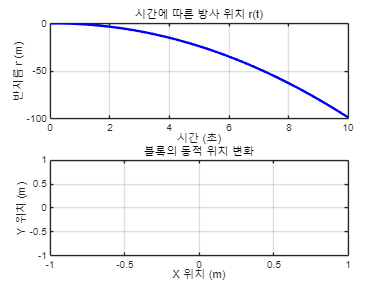


% 시간 변수
t_total = 10; % 전체 시간 (초)
dt = 0.1; % 시간 간격
t = 0:dt:t_total; % 시간 배열

% 초기값 설정
r_initial = r; % 초기 반지름
r_velocity = 0.4; % 초기 방사 속도 (m/s)
r_values = zeros(size(t)); % 위치 값 저장할 배열
r_values(1) = r_initial; % 시작 반지름

% 위치 및 속도 계산
for i = 2:length(t)
    % 속도 업데이트
    r_velocity = r_velocity + ddot_r * dt;
    
    % 위치 업데이트
    r_values(i) = r_values(i-1) + r_velocity * dt;
end

% 그래프 초기 설정
figure;
subplot(2,1,1);
h1 = plot(t, r_values, 'b', 'LineWidth', 2);
title('시간에 따른 방사 위치 r(t)');
xlabel('시간 (초)');
ylabel('반지름 r (m)');
grid on;

% 동적 애니메이션을 위한 설정
theta_values = theta_dot * t; % 각도 변화 (θ = θ_dot * t)
x = r_values .* cos(theta_values); % x 좌표 (극좌표 -> 직교좌표 변환)
y = r_values .* sin(theta_values); % y 좌표

subplot(2,1,2);
h2 = plot(0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
title('블록의 동적 위치 변화');
xlabel('X 위치 (m)');
ylabel('Y 위치 (m)');
axis([-1 1 -1 1]); % 축 설정
grid on;
hold on;

% 동적 그래프 애니메이션
for i = 1:length(t)
    % 첫 번째 그래프 (r vs. t)
    set(h1, 'XData', t(1:i), 'YData', r_values(1:i));
    
    % 두 번째 그래프 (x, y 동적 위치)
    set(h2, 'XData', x(i), 'YData', y(i));
    
    % 애니메이션 업데이트
    drawnow;
    pause(0.05); % 속도 조절을 위해 잠시 멈춤
end

**1. 각도 **$\theta(t)$** 방정식**

각속도 $\dot{\theta} = 3 \, rad/s$가 일정하므로, 각속도는 각도 변화율을 나타냅니다. 이를 적분하면 시간에 따른 각도 $\theta(t)$를 구할 수 있습니다.


$$\dot{\theta} = \frac{d\theta}{dt} = 3 \, rad/s$$


이를 적분하면:


$$\theta(t) = \theta_0 + \dot{\theta} t$$


여기서 $\theta_0$는 초기 각도입니다. 만약 초기 각도가 $30^\circ = \frac{\pi}{6} \, rad$라면, 초기 각도는 $\theta_0 = \frac{\pi}{6} \, rad$입니다. 따라서 시간에 따른 각도 방정식은:


$$\theta(t) = \frac{\pi}{6} + 3t$$


**2. 반지름 **$r(t)$** 방정식**

주어진 문제에서 방사 방향 가속도 $\ddot{r}$는 일정하게 −2.04 m/s2-2.04 \, m/s^2−2.04m/s2로 계산되었습니다. 방사 방향 가속도는 반지름 $r(t)$의 변화율인 속도의 변화입니다.


$$\ddot{r} = \frac{d^2r}{dt^2} = -2.04 \, m/s^2$$


이를 적분하면 속도$\dot{r}$를 구할 수 있습니다. 초기 속도 $\dot{r}(0) = 0.4 \, m/s$가 주어졌으므로, 속도는 다음과 같이 적분됩니다.


$$\dot{r}(t) = \dot{r}_0 + \ddot{r} t = 0.4 \, m/s - 2.04t$$


다시 이 속도를 적분하면 시간에 따른 반지름 $r(t)$을 구할 수 있습니다. 초기 반지름 $r_0 = 0.5 \, m$가 주어졌으므로:


$$r(t) = r_0 + \int \dot{r}(t) \, dt = r_0 + \int (0.4 - 2.04t) \, dt$$


이를 적분하면:


$$r(t) = 0.5 + 0.4t - 1.02t^2$$


따라서, 시간에 따른 반지름 방정식은:


$$r(t) = 0.5 + 0.4t - 1.02t^2$$


**결론:**

- 시간에 따른 각도 방정식:


$$\theta(t) = \frac{\pi}{6} + 3t$$


- 시간에 따른 반지름 방정식:


$$r(t) = 0.5 + 0.4t - 1.02t^2$$


이 두 방정식은 시간 $t$에 따라 블록의 반지름 변화와 각도를 나타냅니다.$ r(t)$는 시간에 따라 감소하며, $\theta(t)$는 시간에 따라 선형적으로 증가합니다.

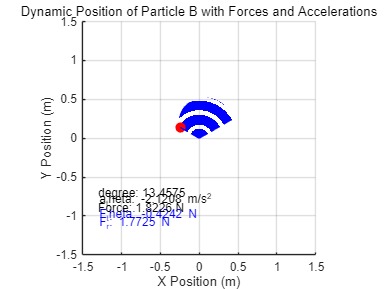

m = 0.2; % 질량 (kg)
t0 = 0; % 초기 시간
t1 = 0.7; 
num_points = 100; 

t_values = linspace(t0, t1, num_points);

F_r = zeros(1, length(t_values)); 
F_theta = zeros(1, length(t_values)); 
Force = zeros(1, length(t_values));
r_values = zeros(1, length(t_values)); 
theta_values = zeros(1, length(t_values)); 
a_r = zeros(1, length(t_values)); 
a_theta = zeros(1, length(t_values)); 

for i = 1:length(t_values)
    t = t_values(i);
    
    r_values(i) = 0.5 + 0.4*t - 1.02*t^2; 
    theta_values(i) = pi/6 + 3 * t; 
    
    dot_r = -2.45 * t; 
    ddot_r = 9; 
    dot_theta = 1 * t; 
    ddot_theta = 1; 
    
    a_r(i) = ddot_r - r_values(i) * dot_theta^2;
    
    a_theta(i) = r_values(i) * ddot_theta + 2 * dot_r * dot_theta;
    
    F_r(i) = m * a_r(i);
    
    F_theta(i) = m * a_theta(i);
    Force(i) = sqrt(F_r(i)^2 + F_theta(i)^2);
    
    tan_theta(i) = abs(F_theta(i) / F_r(i));
    theta_rad(i) = atan(tan_theta(i)); 
    theta_deg(i) = theta_rad(i) * (180 / pi);
end

figure;

hold on;
axis equal;
xlim([-1.5, 1.5]); 
ylim([-1.5, 1.5]); 
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Dynamic Position of Particle B with Forces and Accelerations');
grid on;

% 애니메이션 루프
for i = 1:num_points
    x = r_values(i) * cos(theta_values(i));
    y = r_values(i) * sin(theta_values(i));
   
    if i > 1
        delete(h); 
        delete(txt_r); 
        delete(txt_theta); 
        delete(txt_F); 
        delete(txt_a_theta); 
        delete(txt_tan); 
    end
    
    h = plot(x, y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    plot([0, x], [0, y], 'b--'); % 막대 OA 표시
    
    txt_r = text(-1.3, -1.1, sprintf('F_r: %.4f N', F_r(i)), 'FontSize', 10, 'Color', 'b');
    txt_theta = text(-1.3, -1.0, sprintf('F_theta: %.4f N', F_theta(i)), 'FontSize', 10, 'Color', 'b');
    txt_F = text(-1.3, -0.9, sprintf('Force: %.4f N', Force(i)), 'FontSize', 10, 'Color', 'k');
    txt_a_theta = text(-1.3, -0.8, sprintf('a_theta: %.4f m/s^2', a_theta(i)), 'FontSize', 10, 'Color', 'k');
    txt_tan = text(-1.3, -0.7, sprintf('degree: %.4f', theta_deg(i)), 'FontSize', 10, 'Color', 'k');
    
    pause(0.1);
end

hold off;